Calculates the normalized passive force in muscle fibers with respect to the passive force-length relationship (applies to all muscles in OpenSim musckuloskeletal model)

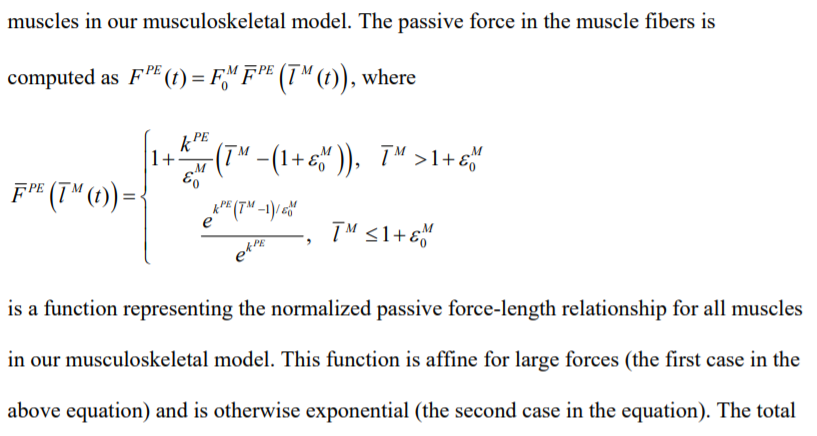


$$\overset{~}{l}$$


function F_PE = Thelen2003_Passive_Force_Length(fib_len)
    k_PE = 4; % an exponential shape factor for the passive force-length relationship
    eM_0 = 0.6; % passive muscle strain due to maximum isometric force
    F_PE = zeros(size(fib_len));
    for i = 1:length(fib_len)
        lM = fib_len(i);
        if lM > (1 + eM_0)
            F_PE(i) = 1 + k_PE/eM_0 * (lM - (1 + eM_0));
        elseif lM <= (1 + eM_0)
            F_PE(i) = exp(k_PE * (lM - 1) / eM_0) / exp(k_PE);
        end
    end        
end